clear variables

fname = 'Job-1.inp';
[Nodes, Elements] = Readmesh(fname);
load simplePlate.mat

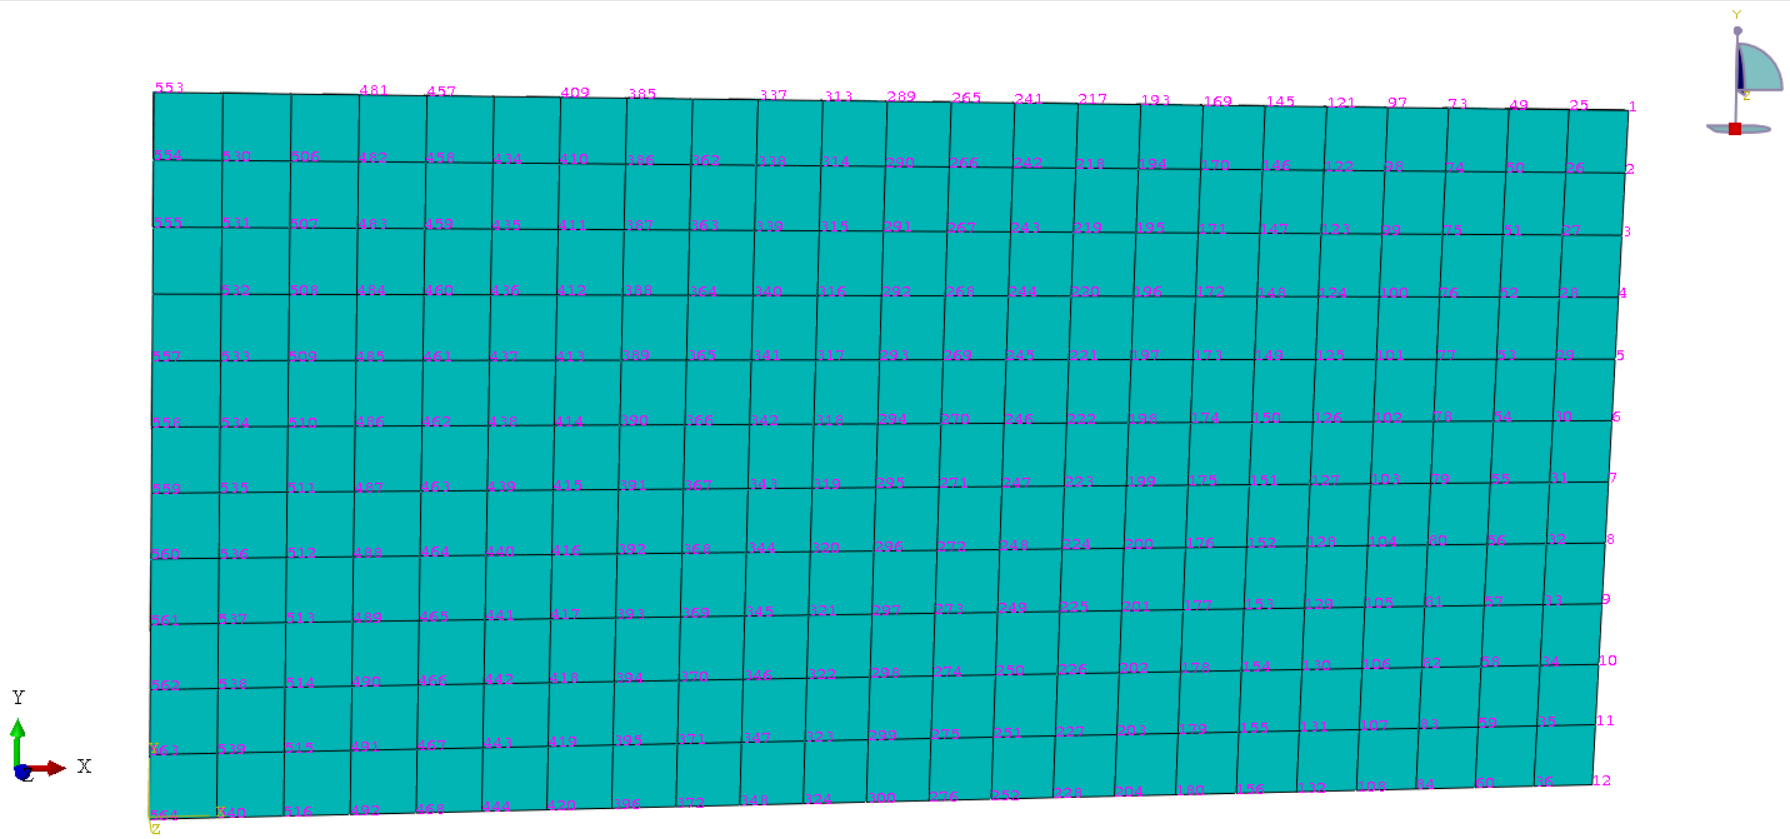

K = globalStiffness;
M = globalMass;
% 对刚度阵进行处理的目的是避免刚度阵不收敛
M_Shell = diag(sum(M));

[dimx,dimy] = find(K>10e30);
K_Shell = K;

% 28,29都没问题，撑得越多越好
K_Shell(sub2ind(size(K_Shell),dimx,dimy)) = K(sub2ind(size(K),dimx,dimy))*10e-29;
Dof = 3;

Forces = [553 3;564 3;409 3;420 3;];
ConDOF = Dof*(Forces(:,1)-1)+Forces(:,2);
% 计算外力自由度编号
Obs = [481 3;492 3;];
ObsDOF = Dof*(Obs(:,1)-1)+Obs(:,2);       % 计算控制点自由度编号

opt = [];

inputDim = size(ConDOF,1);
outputDim = size(ObsDOF,1);
opt.damp.alpha = 0.004;
opt.damp.belta = 0.001;

dim = size(M_Shell,1);
inputsize = size(ConDOF,1);
outputsize = size(ObsDOF,1);

DD = zeros(dim,inputsize);

for i = 1:inputsize
    DD(ConDOF(i,:),i) = 1;
end

C = zeros(outputsize,dim);
for i = 1:outputsize
    C(i,ObsDOF(i,:)) = 1;
end

D = 0.004*K_Shell+0.001*M_Shell;

sys = second2first(M_Shell,D,K_Shell,DD,C);

sysModal = irka(sys,8);

IRKA step 005 - Convergence (combAny):  1.8e-02 7.5e-05 


h2Norm_Modal=norm(sysModal,2)

h2Norm_Modal = 35.8578

h_infNorm_Modal=norm(sysModal,inf)

h_infNorm_Modal = 8.8600

sysDis_Modal = c2d(sysModal,0.005);

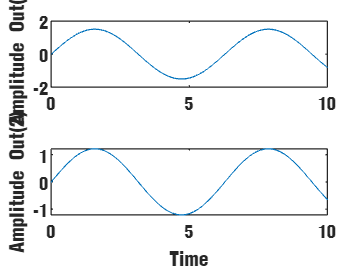

u = @(t) [1*sin(t) * ones(1, 1);0*sin(t) * ones(1, 1);0*sin(t) * ones(1, 1);0*sin(t) * ones(1, 1)];
figure
opts = struct('InputFcn', u, 'TimeRange', 10);
ml_dt_dss_simulate(ss(sysDis_Modal), opts);

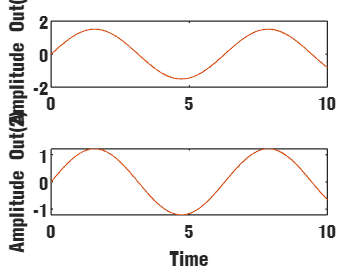

figure
opts = struct('InputFcn', u, 'TimeRange', 10);
ml_ct_dss_simulate_ie(ss(sys),ss(sysModal), opts);

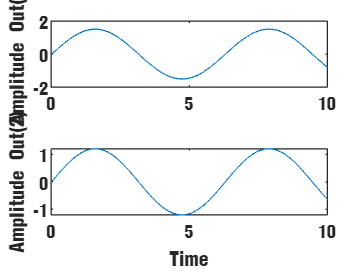

sysDis = c2d(dss2ss(sys),0.02);
figure
opts = struct('InputFcn', u, 'TimeRange', 10);
ml_dt_ss_simulate(ss(sysDis), opts);